# JCNS Fig3: Recurrent Network: Ring; Spike added to V

clear

## Setups

CurrentFolder = pwd;
addpath([CurrentFolder '/Utils'])
HPCPath = [CurrentFolder '/HPCData'];

T = 5000;

% N = 256;NE = 128;NI= 128;
N = 600;NE = 300;NI= 300;


lambda = 0.55;

% I_0 = lambda*f*tau;
fs = [0.07*ones(NE,1);0.07*ones(NI,1)];
NeighborScale = 10; % 60 30 10 5
%Neighbor 5  10 30 60
N_conn = floor(NE/NeighborScale);
S_SWconn = zeros(NE);
for postInd = 1:NE
    for preInd = 1:NE
        if mod(postInd-preInd,NE)<=N_conn/2 | mod(postInd-preInd,NE)>= NE-N_conn/2
            S_SWconn(postInd,preInd) = 1;
        end
    end
end
S = repmat(S_SWconn,2,2);

for jj = 1:N
    S(jj,jj)=0;
end

ssAll = 0.003:0.003:0.03;
N_Sample = 1;
dtAll = [0.1, 0.05];

## Simulations with different S

Vs  = cell(length(ssAll),N_Sample,2);
spike = cell(length(ssAll),N_Sample,2);
SpikeCount = cell(length(ssAll),N_Sample,2);
t   = cell(length(ssAll),N_Sample,2);
spiketime = cell(length(ssAll),N_Sample,2);

for ssInd = 1:length(ssAll)
    ss = ssAll(ssInd);
    see = ss;
    sei = ss*0.9;
    sie = ss*0.9;
    sii = ss;
    
    Nevent = floor(T*lambda*2);
    eventsN = zeros(N,Nevent);
    for ii = 1:N
        event = Poisson_Process_2(lambda,T);
        eventsN(ii,1:length(event))=event;
    end
    
    WinSize  = 2;
    WinSlide = 1;
    %convcurve = [];
    tic
    for SamInd = 1:N_Sample
        V_0s = rand(N,1);
        for dtInd = 1:length(dtAll)
            dt = dtAll(dtInd);
        
            [~,spike{ssInd,SamInd,dtInd},...
             t{ssInd,SamInd,dtInd},SpikeCount{ssInd,SamInd,dtInd},~,Syn(ssInd)] = ...
            MC_Vseries_for_network_ninput_I_based_norms_Syn(dt,T,V_0s,eventsN,fs,S, ...
                                                            see,sei,sie,sii,NE,NI,...
                                                            WinSize, WinSlide);
        [Sp_n,Sp_t] = find(spike{SamInd} == 1);
        spiketime{ssInd,SamInd,dtInd} = (Sp_t-1)*dt;
        end
       
        %convcurve = [convcurve;abs(mean(rate_ns(:,1:6))-mean(rate_ns(:,7)))/N];
    end
    toc
end

历时 10.481422 秒。
历时 10.191591 秒。
历时 11.324948 秒。
历时 10.426842 秒。
历时 10.121030 秒。
历时 13.713533 秒。
历时 10.965418 秒。
历时 13.517127 秒。
历时 12.025890 秒。
历时 12.844499 秒。


## Figure 3

BatchNum = 50; BatchSize = floor((T/WinSlide-2)/BatchNum);
OptR2 = zeros(length(ssAll),BatchNum); % optimal var ratio
FrShow = zeros(length(ssAll),2); % Mean and std

for SInd = 1:length(ssAll)
    tic
    SamInd = 1;
    SpDiff = sum(SpikeCount{SInd,SamInd,1} - SpikeCount{SInd,SamInd,2});
    SpSum = sum(SpikeCount{SInd,SamInd,2});
    
    FrRecord = zeros(1,BatchNum);
    % Now, for each batch
    for BatchInd = 1:BatchNum
        a = (BatchInd-1)*BatchSize+1; b = (BatchInd)*BatchSize;
        r2 = var(SpDiff(a:b),'omitnan')/var(SpSum(a:b),'omitnan'); % Variance ratio: Diff/V2
        
        % allSpDiff = sum(abs(SpDiff(:)))
        rho = sqrt(r2)/sqrt(3); % optimal sample ratio
        OptR2(SInd,BatchInd) = 1/2 + 3/2*rho + r2*(1/(2*rho)+3/2); % optimal var reduction ratio
        
        gridBatchSize = floor(length(t{SInd,SamInd,1})/BatchNum);
        
        c = (BatchInd-1)*gridBatchSize+1; d = (BatchInd)*gridBatchSize;
        FrEventsN = sum(spike{SInd,SamInd,1}(:,c:d),'all');
        FrRecord(BatchInd) = FrEventsN;
    end
    FrShow(SInd,1) = mean(FrRecord/(BatchSize/1000)/N);
    FrShow(SInd,2) = std(FrRecord/(BatchSize/1000)/N);

    
    toc
end

历时 0.128678 秒。
历时 0.109459 秒。
历时 0.114266 秒。
历时 0.107811 秒。
历时 0.105886 秒。
历时 0.104748 秒。
历时 0.102284 秒。
历时 0.113654 秒。
历时 0.116013 秒。
历时 0.117673 秒。


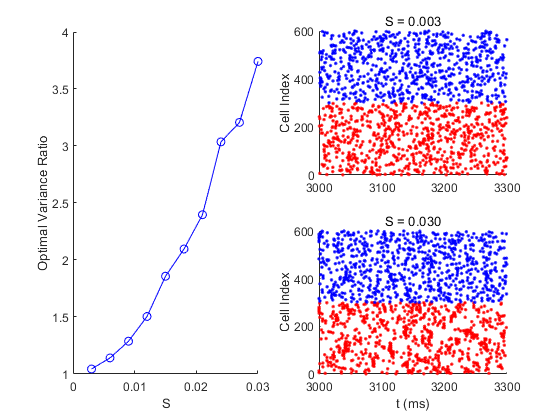


figure('Name','Fig2')
subplot 121
hold on
plot(ssAll,mean(OptR2,2),'b-O')
%errorbar(ssAll,mean(OptR2,2),std(OptR2,[],2)/sqrt(BatchNum),'b.')
% yyaxis right
% plot(SharedProp,mean(RDAll,2),'g-')
% errorbar(SharedProp,mean(RDAll,2),std(RDAll,[],2),'g.')
xlabel('S')
ylabel('Optimal Variance Ratio')
%ylim([0 0.03])

SIndShow  = [1,10];

for SIndShowInd = 1:length(SIndShow)
    subplot(length(SIndShow),2,2*SIndShowInd)
    SInd = SIndShow(SIndShowInd);
    
    SShow = ssAll(SIndShow(SIndShowInd));
    SamInd = 1;
    
    [NeuInds,TInd] = find(spike{SInd,1,2}>0);
    hold on
    scatter(TInd(NeuInds<=NE)*dtAll(2),NeuInds(NeuInds<=NE), 'r.')
    scatter(TInd(NeuInds>NE)*dtAll(2), NeuInds(NeuInds>NE),  'b.')
    hold off
    title(sprintf('S = %.3f',SShow))
    xlim([3000 3300])
    ylabel('Cell Index')
end


subplot(length(SIndShow),2,2*SIndShowInd)
xlabel('t (ms)')